I1 = imread("Fish_Image\Goldfish-1.jpg");
I2 = imread("Fish_Image\Goldfish-3.jpg");

rmat1 = I1(:,:,1);
gmat1 = I1(:,:,2);
bmat1 = I1(:,:,3);
Grmat1 = im2bw(rmat1,0.3);
Ggmat1 = im2bw(gmat1,0.2);
Gbmat1 = im2bw(bmat1,0.1);
IBW1 = (Grmat1&Ggmat1&Gbmat1);
subplot(2,2,1),imshow(Grmat1); title('Red');
subplot(2,2,2),imshow(Ggmat1); title('Green');
subplot(2,2,3),imshow(Gbmat1); title('Blue');
subplot(2,2,4),imshow(IBW1); title('Original');

rmat2 = I2(:,:,1);
gmat2 = I2(:,:,2);
bmat2 = I2(:,:,3);
Grmat2 = im2bw(rmat2,0.4);
Ggmat2 = im2bw(gmat2,0.3);
Gbmat2 = im2bw(bmat2,0.2);
IBW2 = (Grmat2&Ggmat2&Gbmat2);
subplot(2,2,1),imshow(Grmat2); title('Red');
subplot(2,2,2),imshow(Ggmat2); title('Green');
subplot(2,2,3),imshow(Gbmat2); title('Blue');
subplot(2,2,4),imshow(IBW2); title('Original');

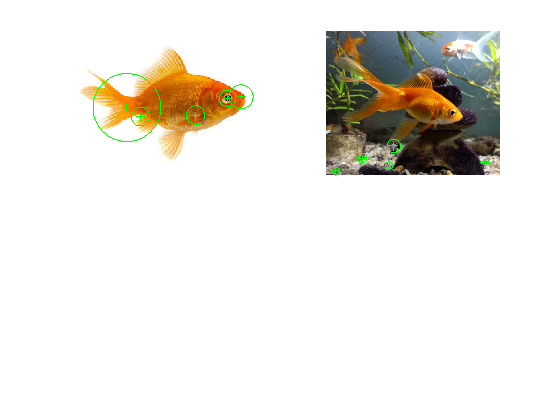

Ipts1 = detectSURFFeatures(IBW1);
Ipts2 = detectSURFFeatures(IBW2);
[Iref1_features,  Iref1_validPts] = extractFeatures(IBW1,  Ipts1);
[Iref2_features,  Iref2_validPts] = extractFeatures(IBW2,  Ipts2);
figure;
subplot(2,2,1);
imshow(I1); hold on;
plot(Ipts1.selectStrongest(5));
subplot(2,2,2);
imshow(I2); hold on;
plot(Ipts2.selectStrongest(5));

figure;
index_pairs = matchFeatures(Iref1_features, Iref2_features);
matchedPoints1 = Iref1_validPts(index_pairs(:,1),:).Location;
matchedPoints2 = Iref2_validPts(index_pairs(:,2),:).Location;
figure; showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2,'montage');

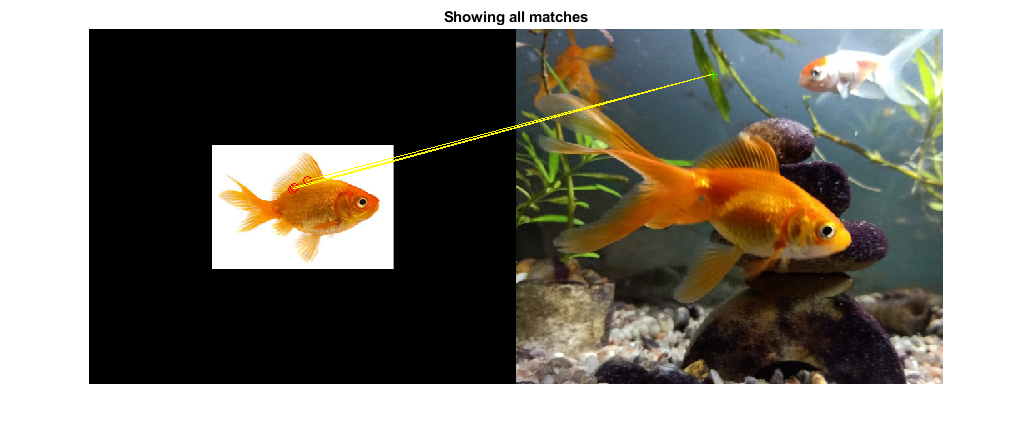

title('Showing all matches');